# Project 1

## **Problem 1**

### a)

We have a object drop from a high, subjected to the forces of gravity and friction du to air resistant. The air resistant can have to states dependig on the state of the parachute. Ther air resistant are 7 times higher with the parachute open. Assuming the gravity are fairly constant at 9.81 m/s^2 at the drop high to the ground. The parachut open at T(min) and the air resitant have a constant described by b. The hight have the constant y.

First we set the constants

[https://www.fallskjerm.no/nb/tandemhopp/](https://www.fallskjerm.no/nb/tandemhopp/)

The b constant for air resistant are a proximaty based on the output, however a fuction for calcuating the air resistand based on the speed squared was found.

syms Fd Cd Ad rho v

Fd = Cd*Ad*rho*v^2

$$Fd = \mathrm{Ad}\,\mathrm{Cd}\,\rho \,v^{2}$$

Cd is 1, Ad is 1.9, rho 1.225, 

bbs = 1*1.9*1.225

bbs = 2.3275

This gives a air resistance of 2.4. This is however based on the speed squared. To compensat 10 was used as a proximity as this worked well with the calculations. A more exact number could be calcuated based on the terminal speed of a human body. This would however change based on the altitude and the proximity of 10 seems reasonable. 

mS = 80;        % Weight oif the man in kg
bS = 10;        % Air resistant constant
hS = 4000;      % Drop height
g = 9.81;       % Acceleration due to gravity

Force due to gravity:

Fg = m*g

Force due to air resistant:

t<T :     Ff = y'*b

t>=T :     Ff = y'*7b

Drop hight;

y(0) = h

Equation:

ma = Ff - Fg

a = (Ff-Fg)/m

y''=(y'*b - m * g)/m

y'' = y'*(b/m) - g

syms y(t) b m

dy = diff(y);

% Differential equation
ode = diff(y,t,2) == - diff(y,t)*(b/m) - g

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=-\frac{b\,\frac{\partial }{\partial t}y\left(t\right)}{m}-\frac{981}{100}$$

ode2 = diff(y,t,2) == - diff(y,t)*(7*b/m) - g

$$ode2(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=-\frac{7\,b\,\frac{\partial }{\partial t}y\left(t\right)}{m}-\frac{981}{100}$$


% Condition
cond = [y(0) == hS dy(0) == 0];
T = 45;

% First part
ySolve(t) = dsolve(ode, cond)

$$ySolve(t) = \frac{400000\,b^{2}+981\,m^{2}}{100\,b^{2}}-\frac{981\,m\,t}{100\,b}-\frac{981\,m^{2}\,{\mathrm{e}}^{-\frac{b\,t}{m}}}{100\,b^{2}}$$

yEnd(t) = subs(ySolve, {b m}, {bS mS})

$$yEnd(t) = \frac{115696}{25}-\frac{15696\,{\mathrm{e}}^{-\frac{t}{8}}}{25}-\frac{1962\,t}{25}$$


Dy = diff(yEnd);
% New conditions
cond2 = [y(T) == yEnd(T) dy(T) == Dy(T)]

$$cond2 = \left(\begin{array}{cc} y\left(45\right)=\frac{27406}{25}-\frac{15696\,{\mathrm{e}}^{-\frac{45}{8}}}{25} & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=45}\right)=\frac{1962\,{\mathrm{e}}^{-\frac{45}{8}}}{25}-\frac{1962}{25} \end{array}\right)$$


% Second part
ySolve2(t) = dsolve(ode2, cond2)

$$ySolve2(t) = \frac{{\mathrm{e}}^{-\frac{45}{8}}\,\left(54936\,b\,m+5371576\,b^{2}\,{\mathrm{e}}^{45/8}+981\,m^{2}\,{\mathrm{e}}^{45/8}-3076416\,b^{2}+254079\,b\,m\,{\mathrm{e}}^{45/8}\right)}{4900\,b^{2}}-\frac{981\,m\,t}{700\,b}-\frac{981\,{\mathrm{e}}^{-\frac{45}{8}}\,{\mathrm{e}}^{-\frac{7\,b\,t}{m}}\,{\mathrm{e}}^{\frac{315\,b}{m}}\,\left(56\,b\,m+m^{2}\,{\mathrm{e}}^{45/8}-56\,b\,m\,{\mathrm{e}}^{45/8}\right)}{4900\,b^{2}}$$

yEnd2(t) = subs(ySolve2, {b m}, {bS mS})

$$yEnd2(t) = \frac{{\mathrm{e}}^{-\frac{45}{8}}\,\left(746699200\,{\mathrm{e}}^{45/8}-263692800\right)}{490000}-\frac{1962\,t}{175}+\frac{981\,{\mathrm{e}}^{-\frac{7\,t}{8}}\,{\mathrm{e}}^{135/4}\,\left(38400\,{\mathrm{e}}^{45/8}-44800\right)}{490000}$$


% Solve for ground hit
hitT = vpasolve(yEnd2 == 0, t,[0 inf])

$$hitT = 135.74853925809801062432001733385$$

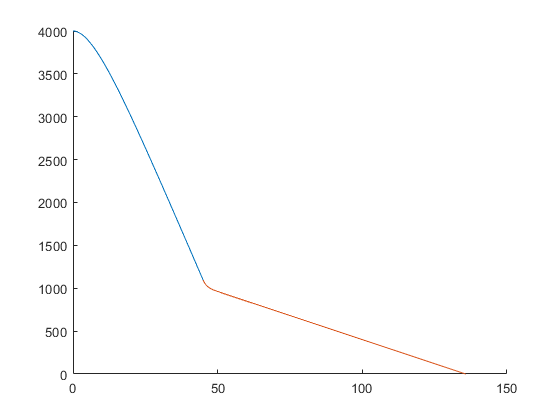


% Plot graph
hold on
ylim([0 hS])
fplot(yEnd,[0 T])
fplot(yEnd2,[T 150])